# SLCO4A - Aula Prática 10

## Transformada de Fourier

A transformada de Fourier é o caminho para expressar no domínio da frequência um sinal que é dado no domínio do tempo.

A transformada de Fourier é denotado pelo símbolo $\Im \left\lbrace \right\rbrace$, ou seja, pode-se escrever


$$X\left(j\omega \;\right)=X\left(\Omega \;\right)=\Im \;\left\lbrace x\left(t\right)\right\rbrace$$


A expressão matemática da transformada de Fourier é dada por:


$$X\left(j\omega \;\right)=\Im \;\left\lbrace x\left(t\right)\right\rbrace =\int_{-\infty \;}^{\infty } x\left(t\right)e^{-j\omega \;t} \textrm{dt}$$


E para retornar para o domínio do tempo a partir do domínio da frequência aplica-se a transformada inversa de Fourier, dada por


$$x\left(t\right)=\Im^{-1} \left\lbrace X\left(j\omega \;\right)\right\rbrace =\frac{1}{2\pi \;}\int_{-\infty \;}^{\infty \;} X\left(j\omega \right)e^{j\omega t} \textrm{dt}$$


### Comandos fourier e ifourier

**Exercício 1:** Compute a transformada de Fourier da função $x\left(t\right)=e^{-t^2 }$.

syms t w
x=exp(-t^2)

$$x = {\mathrm{e}}^{-t^{2}}$$

fourier(x)

$$ans = \sqrt{\pi }\,{\mathrm{e}}^{-\frac{w^{2}}{4}}$$

int(x*exp(-j*w*t), t, -inf, inf)

$$ans = \sqrt{\pi }\,{\mathrm{e}}^{-\frac{w^{2}}{4}}$$

**Exercício 2:** Compute a transformada inversa de Fourier da função $X\left(j\omega \;\right)=\frac{1}{1+j\omega \;}$.

X=1/(1+j*w);
ifourier(X)

$$ans = \frac{{\mathrm{e}}^{-x}\,\left(\mathrm{sign}\left(x\right)+1\right)}{2}$$

syms t w n
X=1/(1+j*w);
ifourier(X, t)

$$ans = \frac{{\mathrm{e}}^{-t}\,\left(\mathrm{sign}\left(t\right)+1\right)}{2}$$

**Exercício 3:** Compute a transformada de Fourier da função $x\left(t\;\right)=1$.

sym w

$$ans = w$$

x=1;
fourier(x, w)

$$ans = 2\,\pi \,\delta (w)$$

Note que o comando `fourier` deve ser executado como `fourier(x,w). `Usando esta sintaxe é a execução ótima que permite o cômputo de funções constantes e de outras funções.

**Exercício 4:** Compute a transformada de Fourier (ou espectro) do sinal $x\left(t\;\right)=e^{-t} u\left(t\right)$e compare o resultado com o exercício 2.

syms t w
x=exp(-t)*heaviside(t);

Note que as funções $x\left(t\right)=e^{-\textrm{at}} u\left(t\right)\leftrightarrow X\left(j\omega \;\right)=\frac{1}{1+j\omega \;}$são um par transformado de Fourier.

### Pares transformados

**Exercício 5:** Considere as seguintes funções obtenha os pares transformados de Fourier.

a) $x\left(t\right)=\delta \;\left(t\right)$

syms t w
x=dirac(t);
fourier(x, w)

$$ans = 1$$

b) $x\left(t\right)=1$

x=1;
fourier(x, w)

$$ans = 2\,\pi \,\delta (w)$$

c) $X\left(j\omega \;\right)=\frac{1}{j\omega \;}+\pi \;\delta \;\left(\omega \;\right)$

X=1/(j*w)+pi*dirac(w)

$$X = \pi \,\delta (w)-\frac{\mathrm{i}}{w}$$

x=ifourier(X,t)

$$x = \frac{\pi +\pi \,\mathrm{sign}\left(t\right)}{2\,\pi }$$

simplify(x)

$$ans = \frac{\mathrm{sign}\left(t\right)}{2}+\frac{1}{2}$$

d) $x\left(t\right)=u\left(t\right)$

x=heaviside(t)

$$x = \mathrm{heaviside}\left(t\right)$$

fourier(x, w)

$$ans = \pi \,\delta (w)-\frac{\mathrm{i}}{w}$$

e) $x\left(t\right)=\delta \left(t-t_0 \right)\;$

syms t0
x=dirac(t-t0)

$$x = \delta (t-t_{0})$$

fourier(x, w)

$$ans = {\mathrm{e}}^{-t_{0}\,w\,\mathrm{i}}$$

f) $X\left(j\omega \;\right)=2\pi \;\delta \;\left(\omega -\omega_0 \right)$

syms w0
X=2*pi*dirac(w-w0);
ifourier(X, t)

$$ans = {\mathrm{e}}^{t\,w_{0}\,\mathrm{i}}$$

g) $X\left(j\omega \;\right)=\pi \;\left(\delta \;\left(\omega -\omega_0 \right)+\delta \;\left(\omega +\omega_0 \right)\right)$

X=pi*(dirac(w-w0)+dirac(w+w0))

$$X = \pi \,\left(\delta (w-w_{0})+\delta (w+w_{0})\right)$$

x=ifourier(X,t)

$$x = \frac{{\mathrm{e}}^{-t\,w_{0}\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,w_{0}\,\mathrm{i}}}{2}$$

simplify(x)

$$ans = \cos\left(t\,w_{0}\right)$$

h)$X\left(j\omega \;\right)=\frac{\pi }{j}\;\left(\delta \;\left(\omega -\omega_0 \right)-\delta \;\left(\omega +\omega_0 \right)\right)$

X=pi/j*(dirac(w-w0)-dirac(w+w0))

$$X = -\pi \,\left(\delta (w-w_{0})-\delta (w+w_{0})\right)\,\mathrm{i}$$

x=ifourier(X, t)

$$x = \frac{{\mathrm{e}}^{-t\,w_{0}\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,w_{0}\,\mathrm{i}}\,\mathrm{i}}{2}$$

simplify(x)

$$ans = \sin\left(t\,w_{0}\right)$$

j)$x\left(t\;\right)=te^{-\mathrm{at}} u\left(t\right)$

syms a
x=t*exp(-a*t)*heaviside(t);
X=fourier(x, w)

$$X = -\left(\frac{\mathrm{sign}\left(\mathrm{real}\left(a\right)\right)}{2}-\frac{1}{2}\right)\,\mathrm{fourier}\left(t\,{\mathrm{e}}^{-a\,t},t,w\right)+\frac{1}{{\left(a+w\,\mathrm{i}\right)}^{2}}$$

simplify(x)

$$ans = t\,{\mathrm{e}}^{-a\,t}\,\mathrm{heaviside}\left(t\right)$$

k)$\textrm{pT}\left(t\right)=\left\lbrace \begin{array}{ll}
1 & \left|t\right|<\frac{T}{2}\\
0 & \left|t\right|>\frac{T}{2}
\end{array}\right.\leftrightarrow T\frac{\sin \left(\frac{\omega T}{2}\right)}{\left(\frac{\omega T}{2}\right)\;}$ , $T=4$

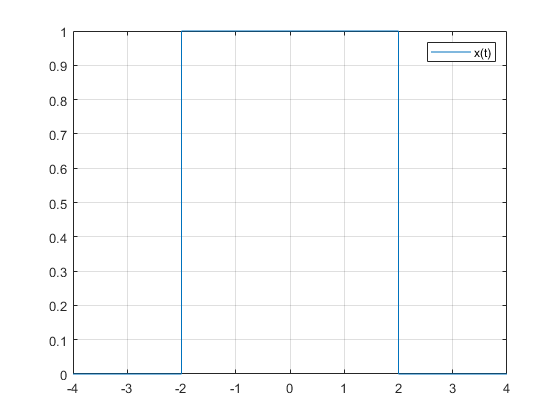

syms t w T
x=heaviside(t+T/2)-heaviside(t-T/2);
xx=subs(x, T, 4);
fplot(xx, [-4 4])
grid on
legend('x(t)')

X1=fourier(x, w)

$$X1 = \frac{\sin\left(\frac{T\,w}{2}\right)+\cos\left(\frac{T\,w}{2}\right)\,\mathrm{i}}{w}-\frac{-\sin\left(\frac{T\,w}{2}\right)+\cos\left(\frac{T\,w}{2}\right)\,\mathrm{i}}{w}$$

simplify(X1)

$$ans = \frac{2\,\sin\left(\frac{T\,w}{2}\right)}{w}$$

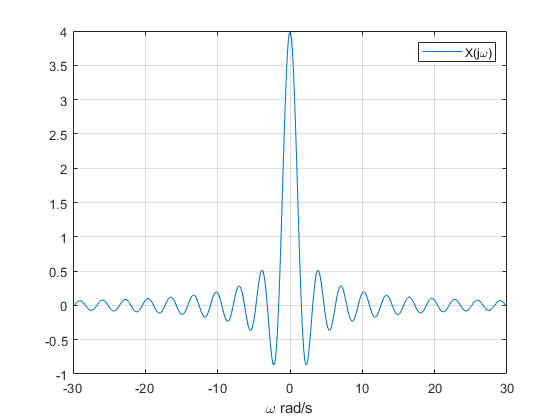

figure
X2=T*(sin(w*T/2)/(w*T/2));
ww=[-30:0.1:-0.1 0.1:0.1:30];
X=subs(X1, w, ww);
X=subs(X, T, 4);
plot(ww, X)
grid on
xlabel('\omega rad/s')
legend('X(j\omega)')

## Propriedades da transformada de Fourier

### Linearidade


$$\Im \;\left\lbrace a_1 x_1 \left(t\right)+a_2 x_2 \left(t\right)\right\rbrace =a_1 X_1 \left(j\omega \;\right)+a_2 X_2 \left(j\omega \;\right)$$


**Exercício 6: **Considere os seguintes sinais $x_1 \left(t\right)=e^{-3t} u\left(t\right)$, $x_2 \left(t\right)={\textrm{te}}^{-t} u\left(t\right)$, $a_1 =3$ e $a_2 =4$.

syms w t
a1=3; a2=4;
x1=exp(-3*t)*heaviside(t);
x2=t*exp(-t)*heaviside(t);
Le=a1*x1+a2*x2;
Lef=fourier(Le, w)

$$Lef = \frac{4}{{\left(1+w\,\mathrm{i}\right)}^{2}}+\frac{3}{3+w\,\mathrm{i}}$$

X1=fourier(x1, w);
X2=fourier(x2, w);
Right=a1*X1+a2*X2

$$Right = \frac{4}{{\left(1+w\,\mathrm{i}\right)}^{2}}+\frac{3}{3+w\,\mathrm{i}}$$

### Deslocamento temporal


$$\Im \;\left\lbrace x\left(t-t_0 \right)\right\rbrace =e^{-j\omega t_0 } X\left(j\omega \;\right)$$


**Exercício 7: **Considere o sinal $x\left(t\right)=\cos \left(t\right)$, $t_0 =2$.

syms t w
x=cos(t);
t0=2;
xt0=cos(t-t0);
Left=fourier(xt0);
simplify(Left)

$$ans = \pi \,\delta (w-1)\,{\mathrm{e}}^{-2\,\mathrm{i}}+\pi \,\delta (w+1)\,{\mathrm{e}}^{2\,\mathrm{i}}$$

X=fourier(x, w)

$$X = \pi \,\left(\delta (w-1)+\delta (w+1)\right)$$

Right=exp(-j*w*t0)*X

$$Right = \pi \,{\mathrm{e}}^{-2\,w\,\mathrm{i}}\,\left(\delta (w-1)+\delta (w+1)\right)$$

simplify(Right)

$$ans = \pi \,\delta (w-1)\,{\mathrm{e}}^{-2\,\mathrm{i}}+\pi \,\delta (w+1)\,{\mathrm{e}}^{2\,\mathrm{i}}$$

### Deslocamento em frequência


$$\Im \;\left\lbrace e^{j\omega_0 t} x\left(t\right)\right\rbrace =X\left(j\left(\omega -\omega_0 \right)\right)$$


**Exercício 8: **Considere o sinal $x\left(t\right)=t^3$, $\omega_0 =3$.

### Escalonamento temporal e na frequência


$$\Im \;\left\lbrace x\left(\textrm{bt}\right)\right\rbrace =\frac{1}{\left|b\right|}X\left(\frac{j\omega }{b}\right)$$



$$\Im \;\left\lbrace \frac{1}{\left|b\right|}x\left(\frac{t}{b}\right)\right\rbrace =X\left(\textrm{bj}\omega \right)$$


**Exercício 9: **Considere o sinal $x\left(t\right)=u\left(t+1\right)-u\left(t-1\right)$, $b=3$.

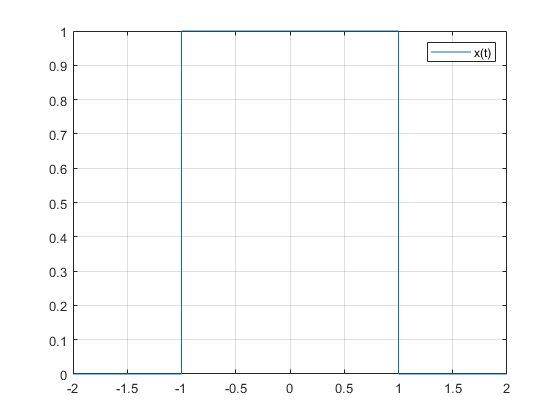

syms t w
b=3;
x=heaviside(t+1)-heaviside(t-1);
fplot(x, [-2 2])
grid on
legend('x(t)')

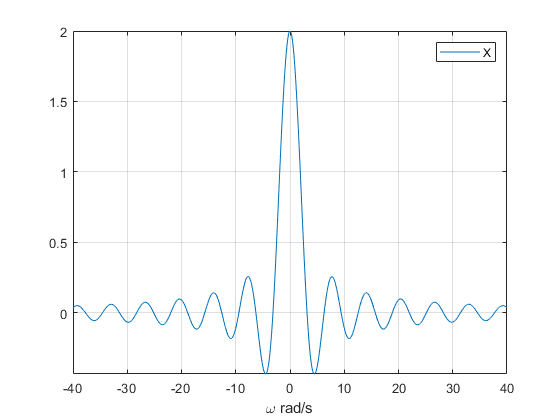

%F{x(t)}
X=fourier(x, w);
fplot(X, [-40 40])
grid on
legend('X')
xlabel('\omega rad/s')

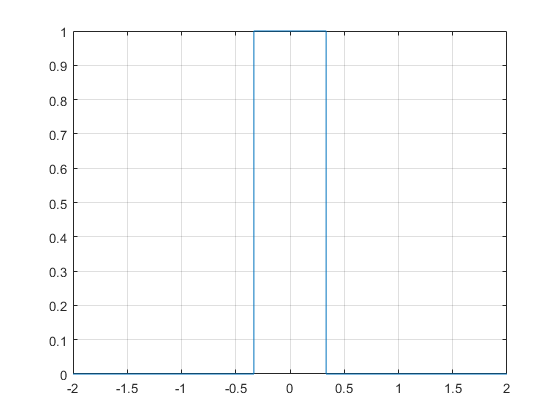

%F{x(bt)}
xb=subs(x, t, b*t);
figure
fplot(xb, [-2 2])
grid on

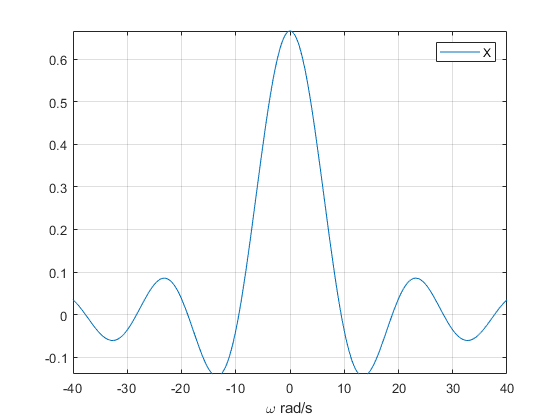

Xb=fourier(xb, w);
fplot(Xb, [-40 40])
grid on
legend('X')
xlabel('\omega rad/s')

### Conjugação

$\Im \;\left\lbrace x^* \left(t\right)\right\rbrace =X^* \left(-j\omega \right)$ e $\Im \;\left\lbrace x^* \left(-t\right)\right\rbrace =X^* \left(j\omega \right)$

**Exercício 10: **Considere o sinal $x\left(t\right)=e^{-2t} u\left(t\right)$.

### Diferenciação no tempo e na frequência

$\Im \;\left\lbrace \frac{\mathrm{d}}{\mathrm{d}t}x\left(t\right)\right\rbrace =j\omega X\left(j\omega \right)$ e $\Im \;\left\lbrace \textrm{tx}\left(t\right)\right\rbrace =j\frac{\mathrm{d}}{\mathrm{d}\omega }X\left(j\omega \right)$

**Exercício 11: **Considere o sinal $x\left(t\right)=e^{-3t} u\left(t\right)$, avalie a diferenciação no tempo e na frequência.

x=exp(-3*t)*heaviside(t);
%F{x'(t)}
xd=diff(x, t);
Left=fourier(xd, w)

$$Left = 1-\frac{3}{3+w\,\mathrm{i}}$$

simplify(Left)

$$ans = \frac{w}{w-3\,\mathrm{i}}$$

X=fourier(x, w);
Right=j*w*X

$$Right = \frac{w\,\mathrm{i}}{3+w\,\mathrm{i}}$$

simplify(Right)

$$ans = \frac{w\,\mathrm{i}}{3+w\,\mathrm{i}}$$

%F{t x(t)}
Left=fourier(t*x, w)

$$Left = \frac{1}{{\left(3+w\,\mathrm{i}\right)}^{2}}$$

der=diff(X, w);
Right=j*der

$$Right = \frac{1}{{\left(3+w\,\mathrm{i}\right)}^{2}}$$

### Integração


$$\Im \;\left\lbrace \int_{-\infty \;\;}^{t\;} x\left(\tau \;\right)d\tau \;\right\rbrace =\frac{1}{j\omega \;}X\left(j\omega \right)+\pi \;X\left(0\right)\delta \;\left(\omega \right)$$


**Exercício 12: **Considere o sinal $x\left(t\right)=\delta \left(t\right)$.

x=heaviside(t);
X=fourier(x, w)

$$x = \pi \,\delta (w)-\frac{\mathrm{i}}{w}$$

syms t tau w
x=dirac(tau)

$$x = \delta (\tau )$$

%F{int(x(tau))
integrau=int(x, tau, -inf, t)

$$integrau = \frac{\mathrm{sign}\left(t\right)}{2}+\frac{1}{2}$$

Left=fourier(integrau)

$$Left = \pi \,\delta (w)-\frac{\mathrm{i}}{w}$$